%Question 1:
x = [3 4 5 7 8 9 11 12];
y = [1.6 3.6 4.4 3.4 2.2 2.8 3.8 4.6];

n = length(x);
M = [n sum(x) sum(x.^2) sum(x.^3);
     sum(x) sum(x.^2) sum(x.^3) sum(x.^4);
     sum(x.^2) sum(x.^3) sum(x.^4) sum(x.^5);
     sum(x.^3) sum(x.^4) sum(x.^5) sum(x.^6)];
r = [sum(y); sum(x.*y); sum(x.^2.*y); sum(x.^3.*y)];
a = M\r;
disp(a);

  -11.4887
    7.1438
   -1.0412
    0.0467



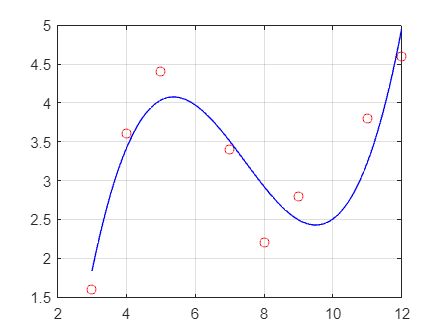


S_r = sum((y - a(1) - a(2).*x - a(3).*(x.^2) - a(4).*(x.^3)).^2);
S_t = sum((y - mean(y)).^2);
r = sqrt((S_t - S_r) / S_t);
Syx = sqrt(S_r / (n - (3 + 1)));

plot(x, y, 'ro');
hold on; grid on;
X = linspace(3, 12);
Y = a(1) + a(2)*X + a(3)*X.^2 +a(4)*X.^3;
plot(X, Y, '-b');

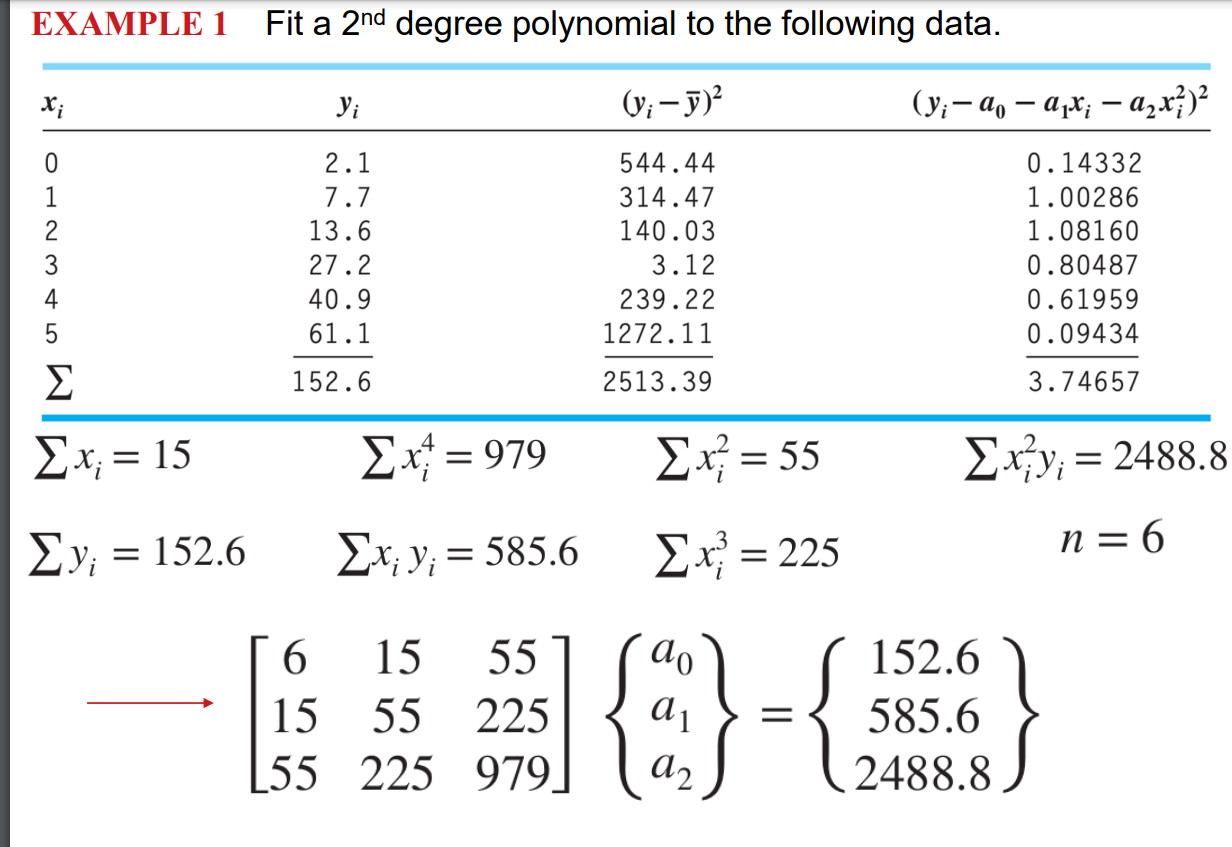

%Example
figure;
x = [0 1 2 3 4 5];
y = [2.1 7.7 13.6 27.2 40.9 61.1];
plot(x, y, 'ob');
hold on; grid on;
n = length(x);
ans1 = (2.1 - mean(y))^2;

Mat = [length(x) sum(x) sum(x.^2);
     sum(x) sum(x.^2) sum(x.^3);
     sum(x.^2) sum(x.^3) sum(x.^4);
];

r = [sum(y); sum(x.*y); sum(x.^2.*y);];
a = Mat\r;

S_t = sum((y - mean(y)).^2);
S_r = sum((y - a(1) - a(2).*x - a(3).*(x.^2)).^2);

r = sqrt(S_r)

r =    1.935606217331261


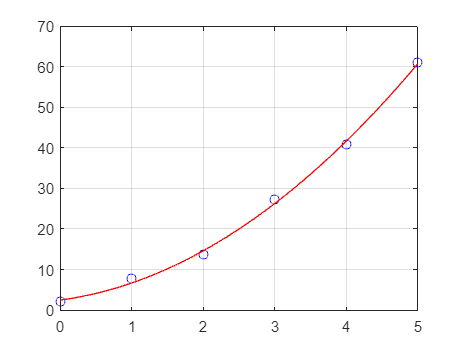


X = linspace(0, 5);
Y = a(3)*X.^2 + a(2)*X + a(1);
plot(X, Y, '-r');
hold off;

%Question 2
x = [3 4 5 7 8 9 11 12]';
y = [1.6 3.6 4.4 3.4 2.2 2.8 3.8 4.6]';
Z = [ones(size(x)) x x.^2 x.^3];
a = (Z'*Z)\(Z'*y);

n = length(x);

S_r = sum((y - a(1) - a(2).*x - a(3).*(x.^2) - a(4).*(x.^3)).^2);
S_t = sum((y - mean(y)).^2);
r = sqrt((S_t - S_r) / S_t);
Syx = sqrt(S_r / (n - (3 + 1)));

plot(x, y, 'ro');
hold on; grid on;
X = linspace(3, 12);
Y = a(1) + a(2)*X + a(3)*X.^2 +a(4)*X.^3;
plot(X, Y, '-b');

%Question 3
x = [10 20 30 40 50 60 70 80];
y = [25 70 380 550 610 1220 830 1450];
A = fminsearch(@fit_power,[1,1],[],x,y)

A =     2.5384    1.4359


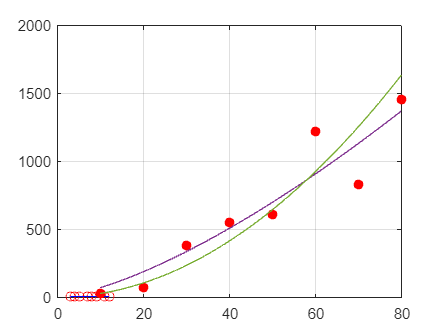

F = @(v) A(1)*v.^(A(2));
plot(x,y,'or','Markersize',6,'Markerfacecolor','r')
hold on
fplot(F,[10,80]);
n = length(y);
S_r = fit_power(A, x, y);
Syx_nonlinear = sqrt(S_r / (n - 2));


A2 = polyfit(log10(x), log10(y), 1);
A2(2) = 10^(A2(2));

S_r_l = fit_power(flip(A2), x, y);
Syx_linear = sqrt(S_r_l / (n - 2));

A2 = flip(A2);

L = @(d) A2(1)*d.^(A2(2));

fplot(L, [10, 80]);

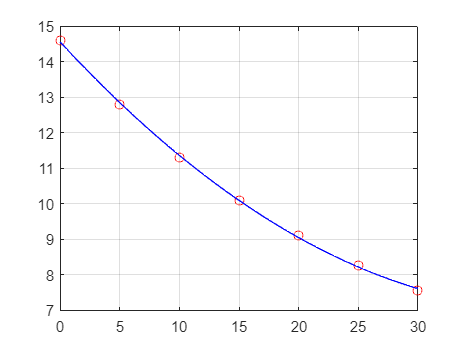

%Question 4
figure;
c0 = [14.6 12.8 11.3 10.1 9.09 8.26 7.56]';
T = [0 5 10 15 20 25 30]';
Z = [ones(size(T)) T T.^2];
a = (Z'*Z)\(Z'*c0);

n = length(T);

plot(T, c0, 'ro');

hold on; grid on;

X = linspace(0, 30);
Y = a(1) + a(2)*X + a(3)*X.^2;
plot(X, Y, '-b');

%Question 5

%Question 6
x1 = [0 1 1 2 2 3 3 4 4];
x2 = [0 1 2 1 2 1 2 1 2];
y = [15.1 17.9 12.7 25.6 20.5 35.1 29.7 45.4 40.2];
n = length(x1);

M = [n sum(x1) sum(x2);
     sum(x1) sum(x1.^2) sum(x1.*x2);
     sum(x2) sum(x1.*x2) sum(x2.*x2);
];

r = [sum(y); sum(x1.*y); sum(x2.*y);];

a = M\r;

S_r = sum((y - a(1) - a(2) * x1 - a(3) * x2).^2);

S_T = sum((y - mean(y)).^2);


r = sqrt((S_T - S_r) / S_T);

Syx = sqrt(S_r / (n - 3));

disp(['Coefficient of Determination (r-squared): ', num2str(r)]);

Coefficient of Determination (r-squared): 0.99776


disp(['Standard Error of the Estimate (Syx): ', num2str(Syx)]);

Standard Error of the Estimate (Syx): 0.88879


%Question 7
q = [.04 .24 .69 .13 .82 2.38 .31 1.95 5.66]; % Y
d = [.3 .6 .9 .3 .6 .9 .3 .6 .9]; % X1
s = [.001 .001 .001 .01 .01 .01 .05 .05 .05]; % X2

n = length(q);

log_q = log10(q);
log_d = log10(d);
log_s = log10(s);

M = [n sum(log_d) sum(log_s);
     sum(log_d) sum(log_d.^2) sum(log_d .* log_s);
     sum(log_s) sum(log_d .* log_s) sum(log_s .* log_s);
];
r = [sum(log_q); sum(log_d .* log_q); sum(log_s .* log_q)];
a = M\r;

a(1) = 10^(a(1));

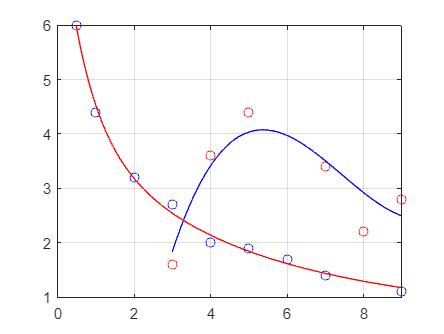

%Question 8
%Original eq: p(t) = A*e^-1.5t + B*e^-0.3t + C*e^-0.05t;
%Ln (p(t)) = (ln(A) + (-1.5t)) + (ln(B) + (-0.3t)) + (ln(C) + (-0.05t))
t = [0.5, 1, 2, 3, 4, 5, 6, 7, 9]';
y = [6, 4.4, 3.2, 2.7, 2, 1.9, 1.7, 1.4, 1.1]';
Z = [ exp(-1.5.*t) exp(-0.3.*t) exp(-0.05.*t)];
a = (Z'*Z)\(Z'*y);
plot(t, y, 'bo');
hold on;
X = linspace(0, 9);
Y = a(1)*exp(-1.5.*X) + a(2)*exp(-0.3.*X) + a(3)*exp(-0.05.*X);
plot(X, Y, '-r');
ylim([1, 6]);
xlim([0, 9]);

%Question 10
sym x

$$ans = x$$

eq = x.^3 + 3*x.^2 - x - 3;
sol = factor(eq)

Error using factor
N must be a scalar.

sol

%Question 11
syms x

% Define the function
y = exp(-3*x^2) * sin(x^7 - 5*x^2);

% Compute the 3rd order Taylor series expansion about x = -1
taylor_series = taylor(y, x, -1, 'Order', 3);

% Display the result
disp(['3rd Order Taylor Series Expansion: ', char(taylor_series)]);

%Question 12


%Question 13
syms x y
y = x^2 * cos(2*x^3) / ((x^2 - 1)^2 - sin(x));
dxdy = diff(y, x);
disp(['Your diff is: ', char(dxdy)]);

%Question 14
clear;
syms x
R = -5*(x^2)*(sin(2*x^3)^3)*cos(2*x^3)
M = int(R);
disp(['Your indefinite integral is: ', char(M)]);

%Question 15
upper_limit = pi/4;
r = subs(M, x, upper_limit);

lower_limit = -pi/3;
l = subs(M, x, lower_limit);

def_int = vpa(r - l);

disp(['Your integral is: ', char(M)]);
disp(['The value of the definite integral at interval x (pi/4) to (-pi/3): ', char(def_int)]);

f = @(x) x.^2 - 4*x + 2;
R = NR_general(f,1);

Root found: 0.58578


f(R);

FUNCTIONS

function Sr = fit_power(a,x_data,y_data)
% a = [alpha, beta]
F_power = a(1)*x_data.^a(2);
Sr = sum((y_data - F_power).^2);
end

function r = NR_general(f,x0)
G = sym(f);
dG = diff(G);
df = matlabFunction(dG);
x(1) = x0+1;
x(2) = x0;
while abs(x(end)-x(end-1)) > 0.01
x(end+1) = x(end) - f(x(end))/df(x(end));
if length(x) > 1002
disp('Stopping. More than 1000 iterations reached.')
break
end
end
r = x(end);
disp(['Root found: ',num2str(r)])
end